%%% Load and filter Unity event Log
% Read TTL_LOG.csv
T = readtable('TTL_LOGS.csv');

% Keep only SampleOn, DistractorOn, TargetOn
mask = ismember(T.Event, {'SampleOn','DistractorOn','TargetOn'});
events = T(mask,:);


% Convert and normalize Unity times

% Unity StopwatchTime is in seconds; convert to ms and zero-reference
unity_ms = (events.StopwatchTime - events.StopwatchTime(1)) * 1000;

%Load and preprocess photodiode and Arduino (TTL) data
states    = readNPY('channel_states.npy');  
channels  = readNPY('channels.npy');        
timestamps= readNPY('timestamps.npy');      % in samples

fs = 30000;  % sampling rate in Hz

% Extract rising edges on photodiode channel (channel 1)
isRisePhoto = (states > 0) & (channels == 1);
tsPhoto = double(timestamps(isRisePhoto)) ./ fs * 1000;  % ms

% Extract rising edges on Arduino channel (channel 8)
isRiseArd   = (states > 0) & (channels == 8);
tsArd = double(timestamps(isRiseArd))   ./ fs * 1000;  % ms

% Filter clusters to first rising edge only
clusterThresh = 200;  % ms
% Photodiode: keep only first in each cluster
keepP = [true; diff(tsPhoto) > clusterThresh];
tsPhoto_filt = tsPhoto(keepP);

% Arduino: similarly if needed
keepA = [true; diff(tsArd)   > clusterThresh];
tsArd_filt   = tsArd(keepA);


%filter arduino pulses more
%% Step 4b. Keep only Arduino pulses that pair with a photodiode flash
matchThresh = 200;  % ms window for "matching" a photo pulse
% For each Arduino timestamp, find the nearest photodiode timestamp
distMat   = abs(tsArd_filt(:) - tsPhoto_filt(:)');
minDist   = min(distMat,[],2);
% Drop any Arduino pulse whose closest photo is >200 ms away
tsArd_filt = tsArd_filt(minDist <= matchThresh);


%normalize zeros
% Unity events zero'd at their own first event
unity_ms   = unity_ms     - unity_ms(1);
photo_ms = tsPhoto_filt - tsArd_filt(1);
ard_ms = tsArd_filt - tsArd_filt(1);



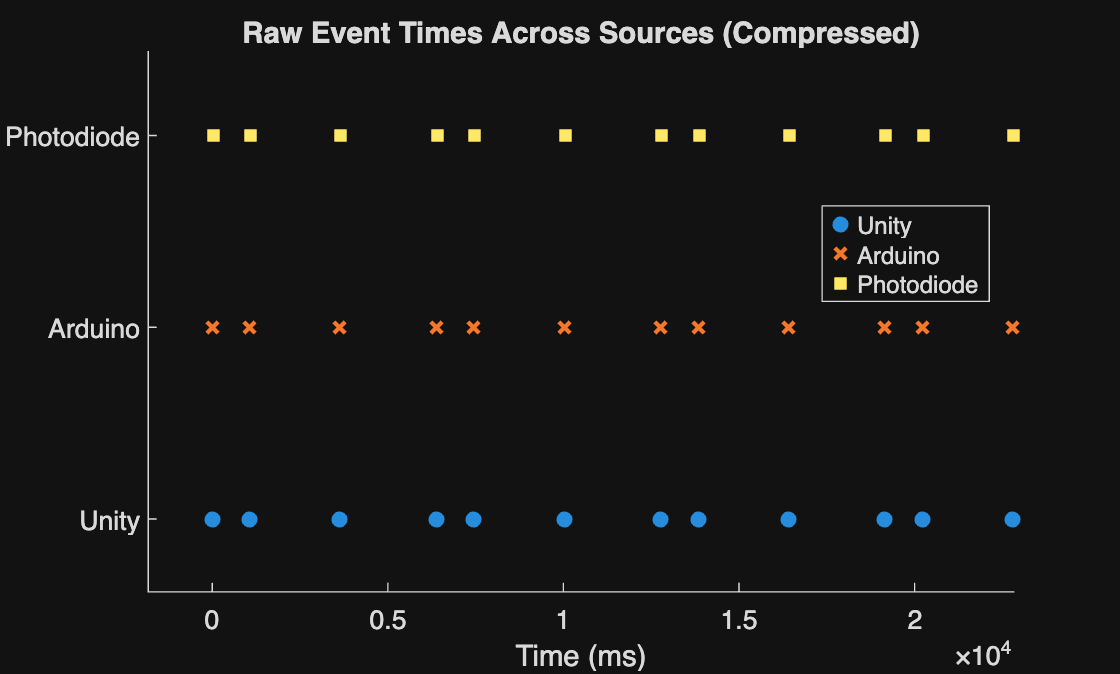

%scatterplots
%%Combined diagnostic scatter with compressed y-axis
figure('Name','Raw Event Alignment','NumberTitle','off'); 
hold on;

% Compressed y-positions
yUnity  = 1   * ones(size(unity_ms));
yArd    = 1.0005* ones(size(ard_ms));
yPhoto  = 1.0010* ones(size(photo_ms));

scatter(unity_ms,  yUnity,  36, 'o', 'filled', 'DisplayName','Unity');
scatter(ard_ms, yArd,    36, 'x', 'LineWidth',1.5, 'DisplayName','Arduino');
scatter(photo_ms,yPhoto, 36, 's', 'filled', 'DisplayName','Photodiode');

yticks([1 1.0005 1.0010]);
yticklabels({'Unity','Arduino','Photodiode'});
ylim([0.95 1.15]);           % Zoom in vertically
xlabel('Time (ms)');
title('Raw Event Times Across Sources (Compressed)');
legend('Location','best');
hold off;

xlim([-1822 22818])
ylim([0.99981 1.00122])
zlim([-1.00 1.00])

%% compute delays for each Unity event
n = numel(unity_ms);
Delay1 = nan(n,1);   % Arduino – Unity
Delay2 = nan(n,1);   % Photo – Arduino
DelayT = nan(n,1);   % Photo – Unity

for i = 1:n
    % 1) Find nearest Arduino pulse
    [~, iA] = min(abs(ard_ms - unity_ms(i)));
    % 2) Find first photodiode flash after that Arduino pulse
    jP = find(photo_ms >= ard_ms(iA), 1, 'first');
    
    Delay1(i) = ard_ms(iA) - unity_ms(i);
    if ~isempty(jP)
        Delay2(i) = photo_ms(jP) - ard_ms(iA);
        DelayT(i) = photo_ms(jP) - unity_ms(i);
    end
end

% ummary statistics
fprintf('Delay_1 (Unity->TTL): mean = %.2f ms,  std = %.2f ms\n', mean(Delay1), std(Delay1));

Delay_1 (Unity->TTL): mean = 2.10 ms,  std = 1.21 ms


fprintf('Delay_2 (TTL->Photodiode): mean = %.2f ms,  std = %.2f ms\n', mean(Delay2), std(Delay2));

Delay_2 (TTL->Photodiode): mean = 28.93 ms,  std = 0.76 ms


fprintf('Delay_total (Unity->Photodiode): mean = %.2f ms,  std = %.2f ms\n', mean(DelayT), std(DelayT));

Delay_total (Unity->Photodiode): mean = 31.04 ms,  std = 1.41 ms


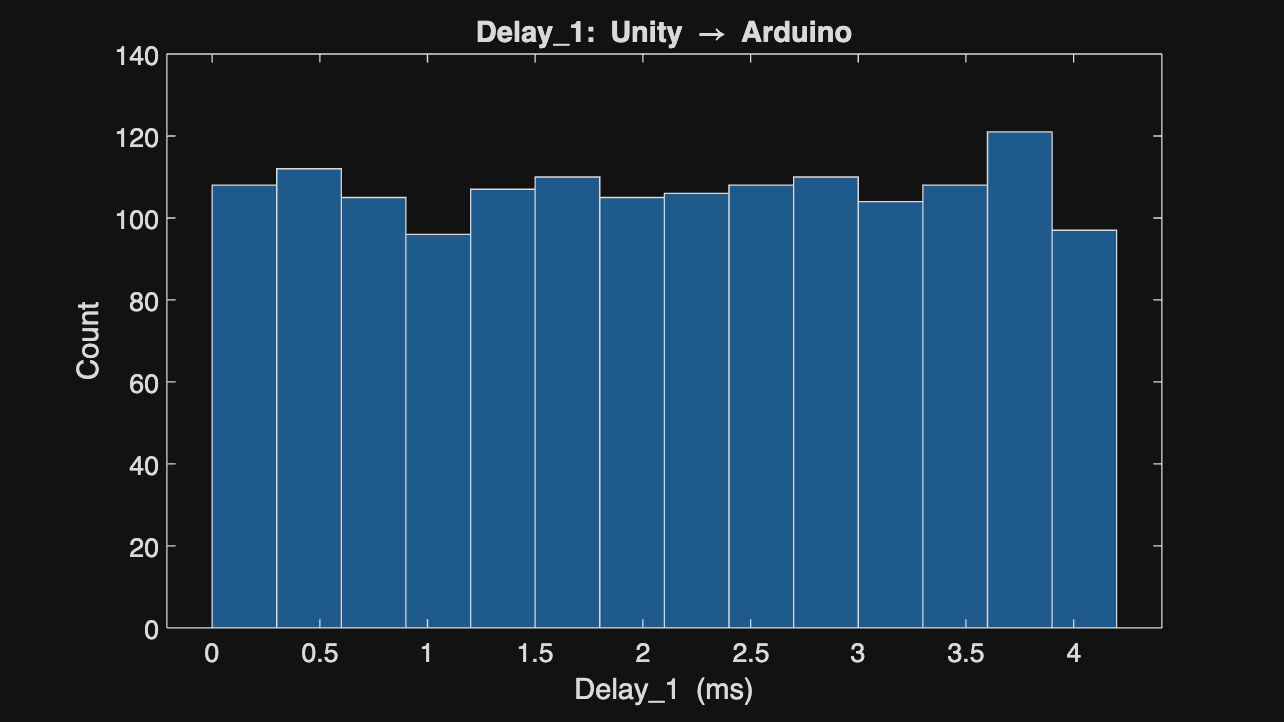


%% Individual full-size histograms 
% Delay_1: Unity → Arduino
fig1 = figure('Name','Delay_1 Histogram','NumberTitle','off');
set(fig1, 'Units','normalized', 'Position',[0 0 1 1]);
histogram(Delay1);
title('Delay\_1: Unity → Arduino');
xlabel('Delay\_1 (ms)');
ylabel('Count');

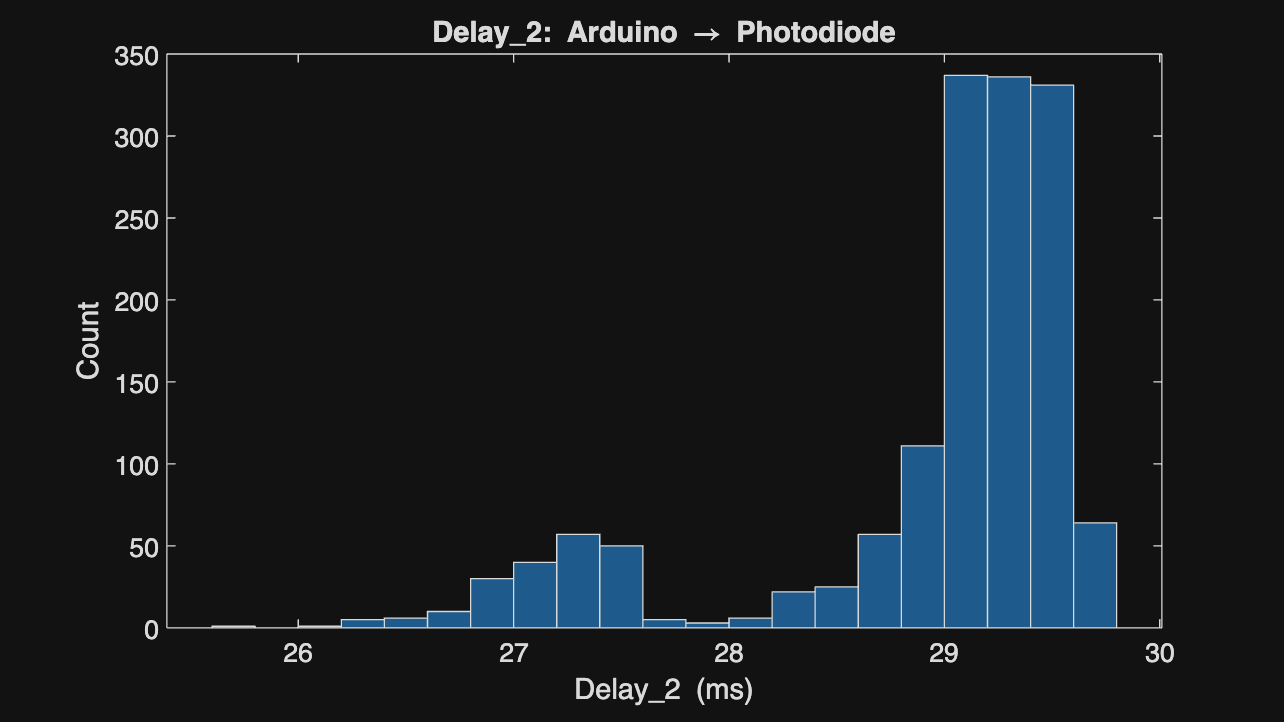


% Delay_2: Arduino → Photodiode
fig2 = figure('Name','Delay_2 Histogram','NumberTitle','off');
set(fig2, 'Units','normalized', 'Position',[0 0 1 1]);
histogram(Delay2);
title('Delay\_2: Arduino → Photodiode');
xlabel('Delay\_2 (ms)');
ylabel('Count');

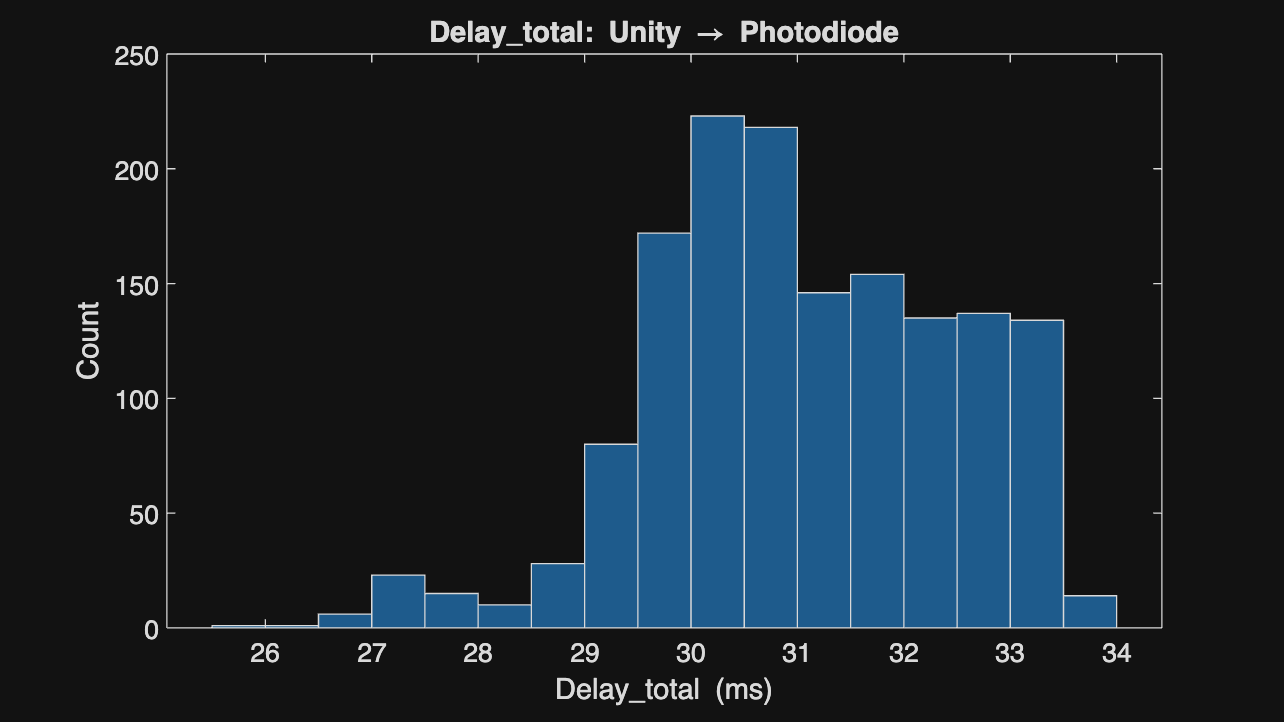


% Delay_total: Unity → Photodiode
fig3 = figure('Name','Delay\_total Histogram','NumberTitle','off');
set(fig3, 'Units','normalized', 'Position',[0 0 1 1]);
histogram(DelayT);
title('Delay\_total: Unity → Photodiode');
xlabel('Delay\_total (ms)');
ylabel('Count');

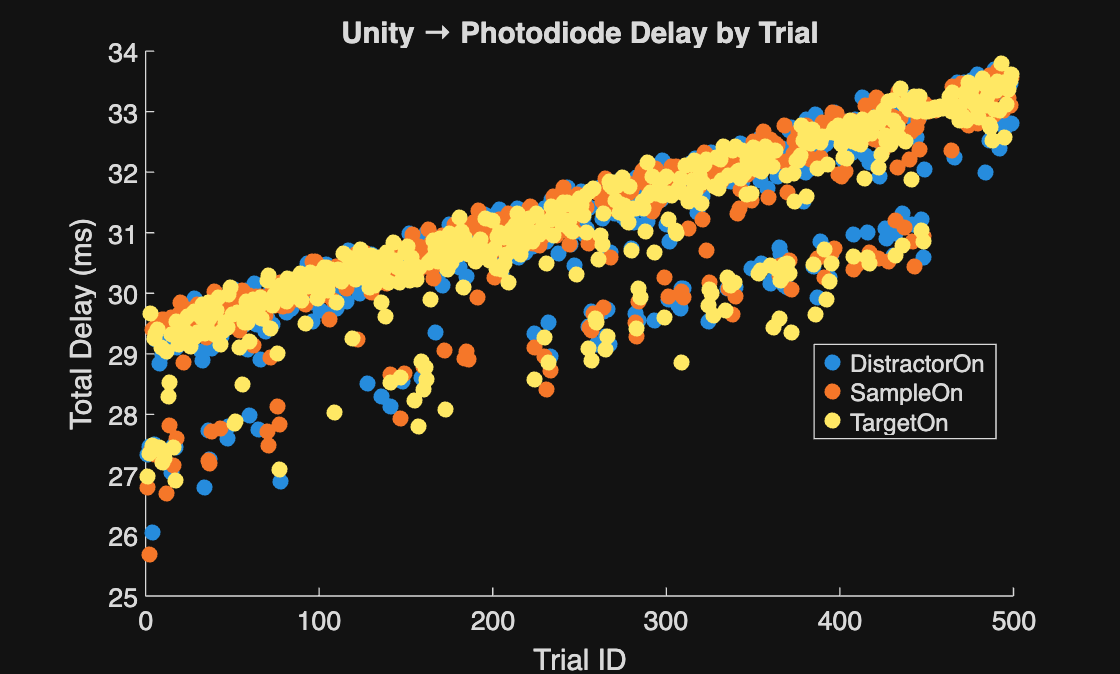



%% Color‐coded scatter of total delay vs. TrialID
trialIDs = events.TrialID;   % grab the trial numbers

figure('Name','Delay vs Trial','NumberTitle','off'); 
hold on;

eventTypes = unique(events.Event);
cols       = lines(numel(eventTypes));
for k = 1:numel(eventTypes)
    idx = strcmp(events.Event, eventTypes{k});
    scatter(trialIDs(idx), DelayT(idx), 36, cols(k,:), 'filled', ...
            'DisplayName', eventTypes{k});
end

xlabel('Trial ID');
ylabel('Total Delay (ms)');
title('Unity → Photodiode Delay by Trial');
legend('Location','best');
hold off;

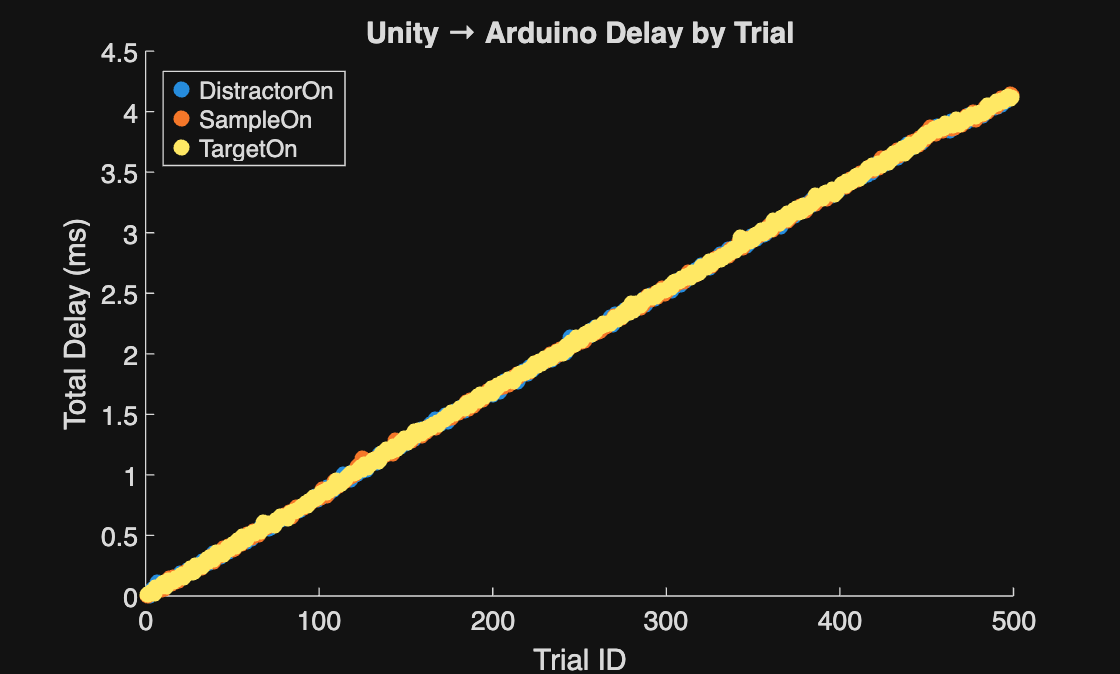



%% Color‐coded scatter of total delay vs. TrialID
trialIDs = events.TrialID;   % grab the trial numbers

figure('Name','Delay vs Trial','NumberTitle','off'); 
hold on;

eventTypes = unique(events.Event);
cols       = lines(numel(eventTypes));
for k = 1:numel(eventTypes)
    idx = strcmp(events.Event, eventTypes{k});
    scatter(trialIDs(idx), Delay1(idx), 36, cols(k,:), 'filled', ...
            'DisplayName', eventTypes{k});
end

xlabel('Trial ID');
ylabel('Total Delay (ms)');
title('Unity → Arduino Delay by Trial');
legend('Location','best');
hold off;

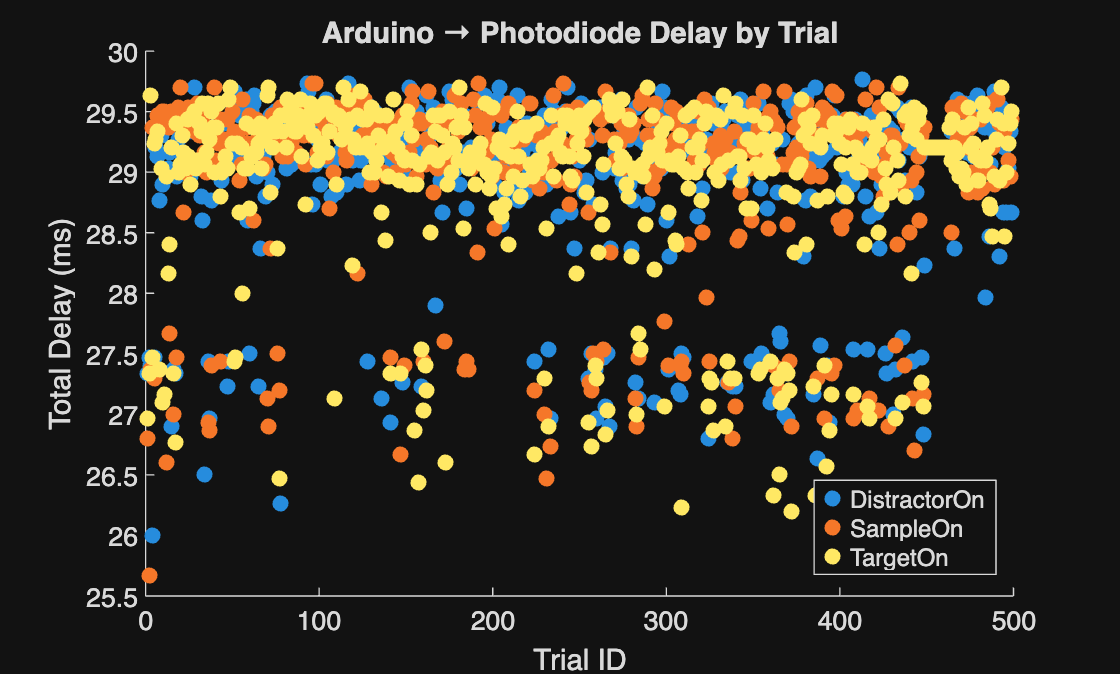



%% Color‐coded scatter of total delay vs. TrialID
trialIDs = events.TrialID;   % grab the trial numbers

figure('Name','Delay vs Trial','NumberTitle','off'); 
hold on;

eventTypes = unique(events.Event);
cols       = lines(numel(eventTypes));
for k = 1:numel(eventTypes)
    idx = strcmp(events.Event, eventTypes{k});
    scatter(trialIDs(idx), Delay2(idx), 36, cols(k,:), 'filled', ...
            'DisplayName', eventTypes{k});
end

xlabel('Trial ID');
ylabel('Total Delay (ms)');
title('Arduino → Photodiode Delay by Trial');
legend('Location','best');
hold off;

%% Please let me know kyle@coutray.com if you have any issues replicating this type of analysis for your own lab setup!